### 圆孔的菲涅尔衍射

clear all
close all
lambda = 0.6*1e-6;
delta = 10*lambda;
z = 10000;
M = 501;

[X,Y] = meshgrid(-250:250,-250:250);
THOR = sqrt(X.^2 + Y.^2)*delta;
OB = zeros(M);
OB(THOR<=5*1e-4) = 1;

P = exp(-i/lambda/z.*(THOR.^2));
U2 = fftshift(fft2(ifftshift(OB.*P)))

U2 = 	1.0e+04 *

  -0.0017 + 0.0000i  -0.0008 + 0.0000i   0.0006 - 0.0000i   0.0019 - 0.0000i   0.0024 - 0.0000i   0.0018 - 0.0000i   0.0004 - 0.0000i  -0.0011 + 0.0000i  -0.0018 + 0.0000i  -0.0012 + 0.0000i   0.0001 - 0.0000i   0.0014 - 0.0000i   0.0018 - 0.0000i   0.0012 - 0.0000i  -0.0001 + 0.0000i  -0.0012 + 0.0000i  -0.0016 + 0.0000i  -0.0014 + 0.0000i  -0.0008 + 0.0000i  -0.0002 + 0.0000i   0.0004 - 0.0000i   0.0006 - 0.0000i   0.0005 - 0.0000i  -0.0001 + 0.0000i  -0.0010 + 0.0000i  -0.0016 + 0.0000i  -0.0014 + 0.0000i  -0.0003 + 0.0000i   0.0013 - 0.0000i   0.0024 - 0.0000i   0.0024 - 0.0000i   0.0013 - 0.0000i  -0.0002 + 0.0000i  -0.0013 + 0.0000i  -0.0015 + 0.0000i  -0.0010 + 0.0000i  -0.0005 + 0.0000i  -0.0002 + 0.0000i  -0.0003 + 0.0000i  -0.0003 + 0.0000i  -0.0002 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0001 + 0.0000i  -0.0003 + 0.0000i  -0.0003 + 0.0000i  -0.0001 + 0.0000i   0.0001 - 0.0000i   0.0002 - 0.0000i   0.0001 - 0.0000i
  -0.0008 + 0.0000i  -0.0005 + 0

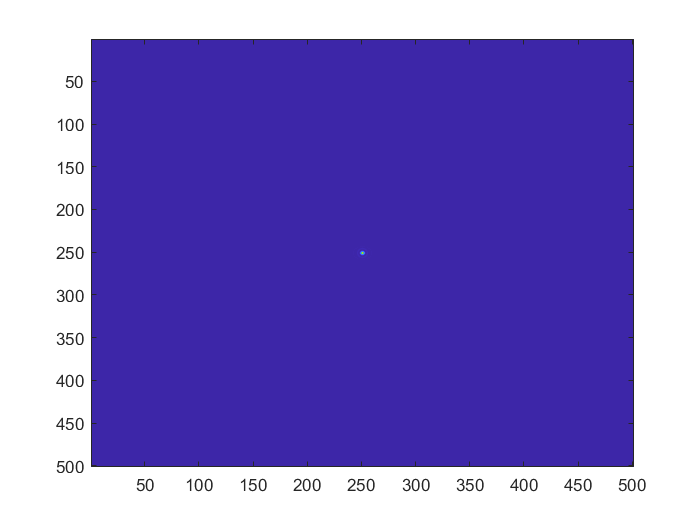

figure
imagesc(abs(U2).^2)